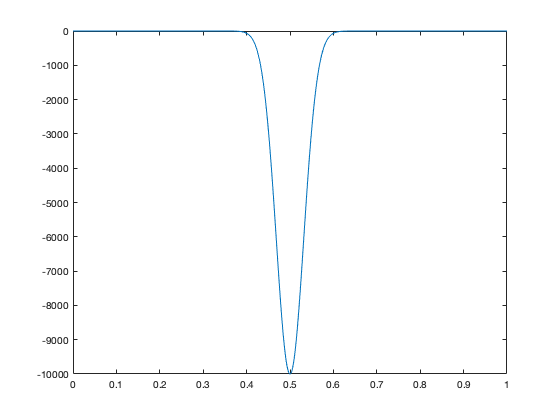

close all
clear
clc

hbar = 1;
m = 1;

L = 1;
Nx = 1000;
Nt = 1e5;
dx = 1/Nx;
dt = 1/Nt;
x = linspace(0, L, Nx)';

u0 = sqrt(2).*sin(1*pi*x(:));
% u0 = 0.00001*abs(exp(1i*(pi*x(:) + pi/2)));

V = -1e4.*exp(-(x - L/2).^2/(2*dx));

% V = 50*(x(:) - 0.5).^2;

% V = 0*x(:)./x(:);
% for j = 1:Nx/3
%     V(j) = -2e4;
%     V(Nx - j) = -2e4;
% end

% V = 2e4*x(:)./x(:);
% for j = 1:Nx/3
%     V(j) = 0;
%     V(Nx - j) = 0;
% end

% V = 1e5*((x(:)+1).^(-12) - (x(:)+1).^(-6));

% V = -1./(x(:)+0.001);

plot(x,V)

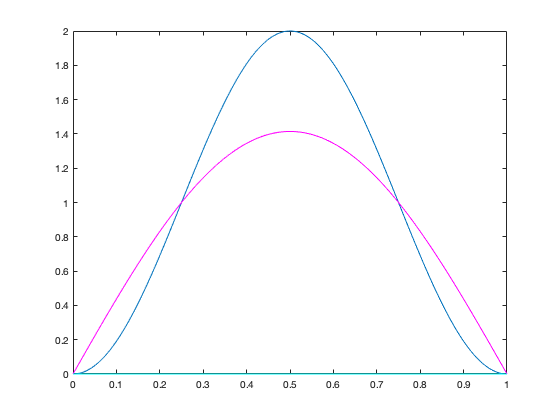


a = dt.*V/(2*hbar);
b = dt*hbar/(4*m*dx*dx);

u = zeros(Nx, Nt);
u(:, 1) = u0;

I = zeros(Nx, Nx);
I(1, 1) = 1;
I(Nx, Nx) = 1;
A = zeros(Nx, Nx);
A(1, 1) = a(1) + 2*b;
A(1, 2) = -b;
A(Nx, Nx-1) = -b;
A(Nx, Nx) = a(Nx) + 2*b;

for j = 2:Nx-1
    A(j, j-1) = -b;
    A(j, j) = a(j) + 2*b;
    A(j, j+1) = -b;

    I(j, j) = 1;
end

U = (I - 1i.*A)/(I + 1i.*A);

for t = 1:Nt
    u(:, t+1) = U*(u(:, t)./(sqrt( abs( u(:, t)'*u(:, t) ) )));
end


plot(x, abs(u(:, 1)).^2, x, real(u(:, 1)), 'm', x, imag(u(:, 1)), 'c');

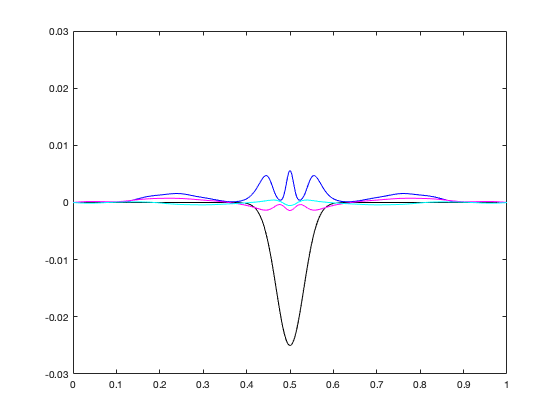


for t = 1:Nt/100

%     plot(x, real(u(:, t)), x, imag(u(:, t)));
    plot(x, abs(u(:, t)).^2, 'b', x, V(:)/4e5, 'k', x, real(u(:, t))/50, 'm', x, imag(u(:, t))/50, 'c');
    axis([0 1 -0.03 0.03]);

    pause(0.00000001)
end